## Oceanus - Tester of Sender Functions

Author: Michel Barbeau, Carleton University

Draft version: March 27, 2021

Test the sender functions.

% cd /Users/michelbarbeau/Dropbox/MyLiveScripts/Oceanus
% 
% clear all;
close all;
% constraint
K = 32;
% pad message with K-1 zeros
% data = [1 1 0 1 0 1 0 0 0 0 1 0 1 1 0 0 0 1 1 1 0 0 1 1 1 1 1 0 1 0 1 1 0 0 1 1 1 0 1 0 0 1 1 1 0 1 1 1 1 0 zeros(1,K-1)];
% Ahmad's string 20210327
data = [0     0     1     0     0     0     1     1     0     1     0     1     1     0     1     1     1     0     1     0     0     1     1     0     1     1     1     1     0     0     0     1     0     0     1     0     1     0     1  1     0     1     0     0     1     1     1     0     0     0 zeros(1,K-1)];
% Ahmad's string 20210327, 1st & 2nd bits flipped
% data = [1    1     1     0     0     0     1     1     0     1     0     1     1     0     1     1     1     0     1     0     0     1     1     0     1     1     1     1     0     0     0     1     0     0     1     0     1     0     1  1     0     1     0     0     1     1     1     0     0     0 zeros(1,K-1)];
% generate the channel symbol
symbols = uwspr_framer(data);
disp(symbols);

  Columns 1 through 25

     3     1     2     0     0     2     0     2     1     2     2     0     3     3     3     0     2     2     1     0     2     1     2     3     3

  Columns 26 through 50

     1     3     0     2     2     0     0     0     2     3     0     2     3     2     1     0     0     2     2     0     2     1     2     3     1

  Columns 51 through 75

     2     0     1     3     0     3     2     0     0     3     3     0     1     0     2     2     0     1     1     0     3     0     1     2     3

  Columns 76 through 100

     2     1     2     0     3     2     0     3     0     3     3     2     2     0     3     3     0     1     2     3     2     0     0     3     2

  Columns 101 through 125

     0     0     0     0     1     2     2     3     2     0     1     1     1     2     3     1     0     2     1     1     0     1     2     0     0

  Columns 126 through 150

     1     3     1     2     2     0     2     0     3     2     3     2     2     3  

% Mode index (1..6)
mode = 1;
% Frame interval vs mode (minutes)
interval = [1 2 4 8 16 20];
% samples per symbol vs mode
spsymbol = [128 256 512 1024 2048 2560];
% generate the complex envelope of baseband signal
y = uwspr_modulator(symbols, spsymbol(mode));
% NOTE: To be compatible with the format used in the rest of the program use y'
disp(size(y));

           1       20736



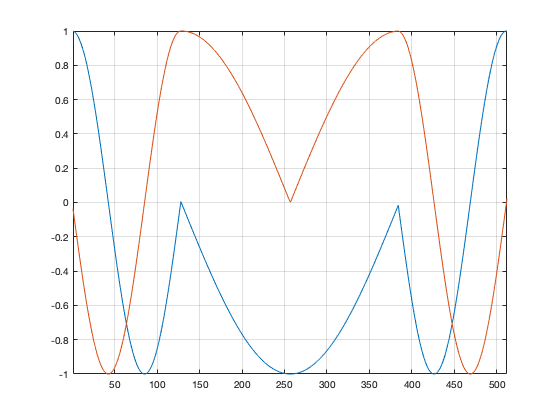

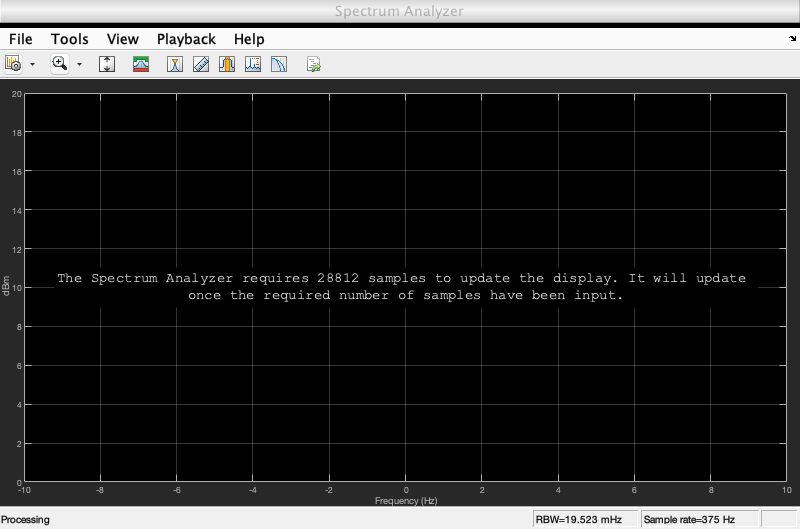

figure;
% plot the first n symbols
n = 4 ;
plot(real(y(1:n*spsymbol(mode))));
hold on;
plot(imag(y(1:n*spsymbol(mode))));
xlim([1 n*spsymbol(mode)])
grid on;
h = dsp.SpectrumAnalyzer('SampleRate',375);
h.FrequencySpan = "Start and stop frequencies";
h.StartFrequency = -10;
h.StopFrequency = 10;
h.YLimits = [-0,20];
step(h,y');

%
% Generate WAV file
%
% 2. Carrier frequency
f = 209; % Hz
% 3. Time offset (random quiet time prefix, in seconds, in [0,9])
toffset = 1; % second
% 4. Output file sampling frequency
oSps = 12000; % samples/sec (a multiple of 375, e.g. 6K, 12K, 24K, 48K, 96K)
% 5. Output file name (broadband signal in ".wav" format)
oFile = int2str(f)+"_"+int2str(oSps)+"_"+int2str(mode)+".wav"; % use frequency number and sampling frequency
fprintf('Output file name: %s\n', oFile);

Output file name: 209_12000_1.wav


% 6. Bits per sample
BitsPerSample = 16;
%%% up conversion
%
% extend the signal to [1 2 4 8 16 20] minutes
z = [y zeros(1,375*interval(mode)*60-length(y))];
% up sampling factor
upSampling = oSps / 375;
% resample the baseband signal for the ".wav" format
x = resample(z,upSampling,1);
% number of time points, 
xl = oSps*interval(mode)*60;
% generate time points
T = interval(mode)*60; % period (seconds)
dt = T/xl; % sample period (second)
t = 0:dt:T-dt;
% modulation
yy = x.*exp(-1i*(2*pi*f.*t));
% normalize in the [-1 1] range
yn = yy/( max( abs(min(yy)), max(yy) ) );
% add a random noise prefix during time offset
% r=rand(1,round(toffset*oSps)); ynn = [ r  yn];
ynn = [zeros(1,oSps*toffset) yn];
% write the wave file
audiowrite(oFile,real(ynn),oSps,'BitsPerSample',BitsPerSample);